# The SI Model

#### **The Model**

The SI model is the simplest form of all compartmental disease models. Individuals are born into the simulation with no immunity, therefore they are susceptible.The dynamics of the infected in a SI model are also known as logistic growth, once infected and with no treatment, individuals stay infected and infectious throughout their life, and remain in contact with the susceptible population. This model matches the behavior of diseases like herpes.

This model for the spread of a disease is dependant upon the state variables S and I.

The image below shows what the block diagram for the SI model looks like.

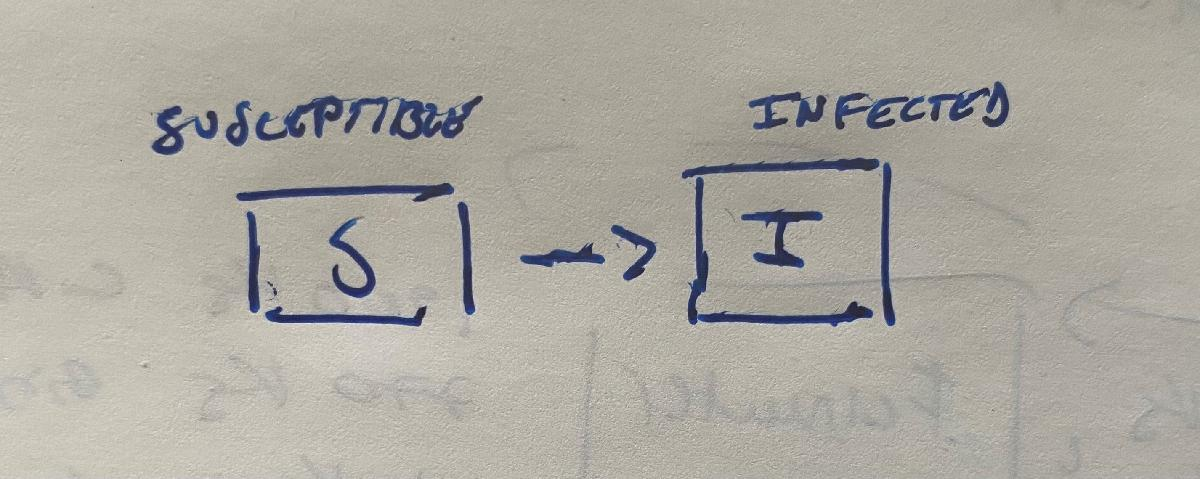

The differential equations of the SI model are:


$$$$\frac{dS}{dt}=- \beta I S$$



$$$$\frac{dI}{dt}=\beta IS$$


where $N=S+I$ is the total population

The parameters are:

- $\beta$ is referred to as the infection rate and is defined as the product between the infection probability $p$ and the contact rate $c$, divided by the total population. In fact, its value depends on the transmissability of the disease, which is accounted for with $p$, and the frequency that members of a population gather for social reasons, which is expressed as $c$.

## Solution with Euler method

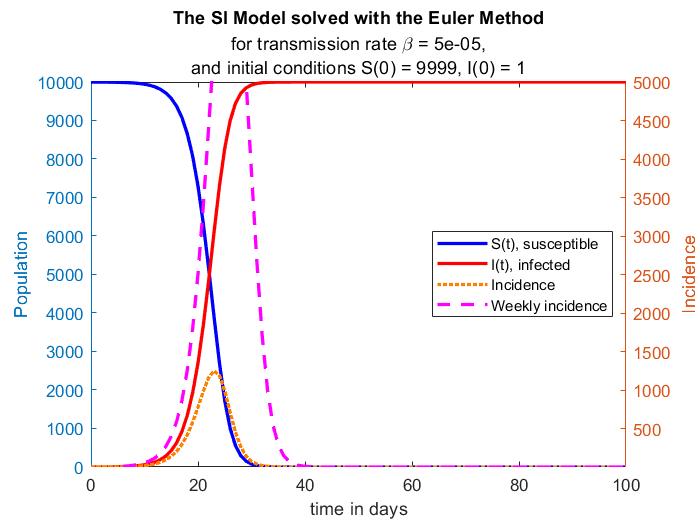

figure;

%%% The initial values

tmax = 100;

S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);

S(1) = 9999;
I(1) = 1;
N=S(1)+I(1);

Incidence = zeros(1, tmax + 1);
Incidence(1) = 0;

Weekly_Incidence = zeros(1, tmax - 6);

%%% The parameters

p=0.1;  % infection probability 
c=5;    % contact rate

beta = p*c/N;


%%% The Euler method

T = zeros(1,tmax + 1);
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
    
    S(t+1) = S(t) - beta*I(t)*S(t);   
    I(t+1) = I(t) + (beta*I(t)*S(t));    
    
    Incidence(t+1) = beta*I(t)*S(t);
    
        if t > 5
                
            Weekly_Incidence(t-5) = sum(Incidence(t-5:t+1));
            
        end
end


%%%% The plot

yyaxis left
plot(T, S, 'b','LineWidth',2,'LineStyle',"-"); hold on;
plot(T, I, 'r','LineWidth',2,'LineStyle',"-");
ylabel('Population');

yyaxis right 
plot(T, Incidence, 'Color',[1 0.5 0],'LineWidth',2,'LineStyle',":");
plot(T(7:end), Weekly_Incidence, 'm', 'Linewidth',2,'LineStyle',"--")
ylim([1 5000]);
ylabel('Incidence');

title('The SI Model solved with the Euler Method')
subtitle({['for transmission rate \beta = ',num2str(beta),','], ...
    ['and initial conditions S(0) = ',num2str(S(1)),', I(0) = ',num2str(I(1))]})
legend('S(t), susceptible', 'I(t), infected','Incidence', 'Weekly incidence', 'Location', 'east')

xlabel('time in days');
xlim([0 100]);

hold off;